## Unipolar NRZ

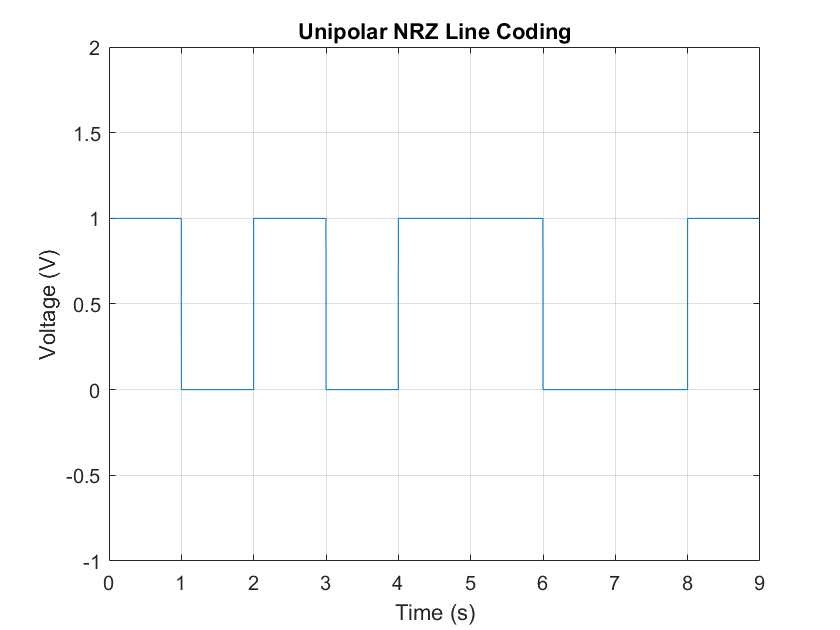

% Define the binary sequence
binary_sequence = [1 0 1 0 1 1 0 0 1];

% Define the bit duration and sampling rate
bit_duration = 1; % Set this as needed
sampling_rate = 1000; % Set this as needed

% Calculate the time vector
t = 0:1/sampling_rate:bit_duration * length(binary_sequence) - 1/sampling_rate;

% Initialize the signal
signal = zeros(1, length(t));

% Create the Unipolar NRZ signal
for i = 1:length(binary_sequence)
    if binary_sequence(i) == 1
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = 1; % High voltage for '1'
    else
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = 0; % Low voltage for '0'
    end
end

% Plot the Unipolar NRZ signal
plot(t, signal);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Unipolar NRZ Line Coding');
ylim([-1, 2]); % Set the y-axis limits as needed
grid on;

## Polar NRZ

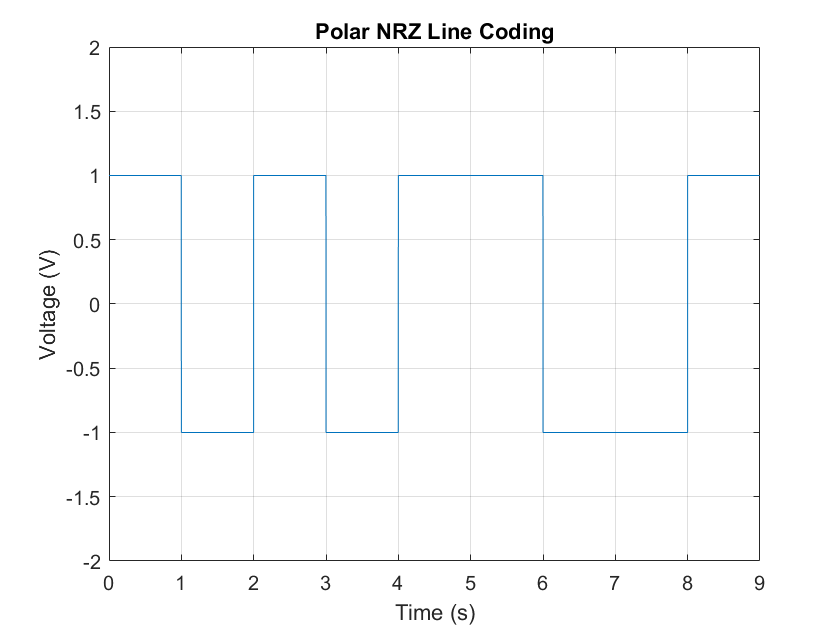

% Define the binary sequence
binary_sequence = [1 0 1 0 1 1 0 0 1];

% Define the bit duration and sampling rate
bit_duration = 1; % Set this as needed
sampling_rate = 1000; % Set this as needed

% Calculate the time vector
t = 0:1/sampling_rate:bit_duration * length(binary_sequence) - 1/sampling_rate;

% Initialize the signal
signal = zeros(1, length(t));

% Create the Polar NRZ signal
for i = 1:length(binary_sequence)
    if binary_sequence(i) == 1
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = 1; % High voltage for '1'
    else
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = -1; % Low voltage for '0'
    end
end

% Plot the Polar NRZ signal
plot(t, signal);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Polar NRZ Line Coding');
ylim([-2, 2]); % Set the y-axis limits as needed
grid on;

## Bipolar NRZ

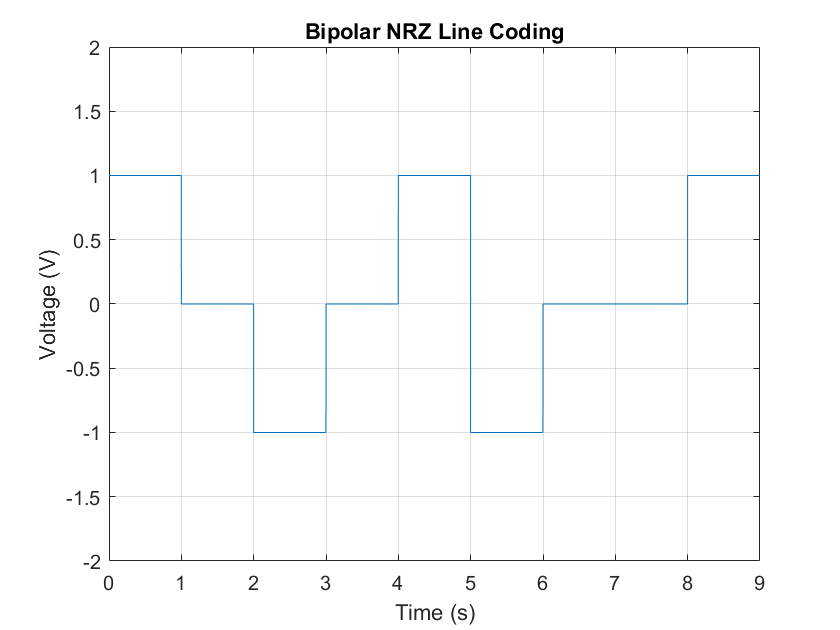

% Define the binary sequence
binary_sequence = [1 0 1 0 1 1 0 0 1];

% Define the bit duration and sampling rate
bit_duration = 1; % Set this as needed
sampling_rate = 1000; % Set this as needed

% Calculate the time vector
t = 0:1/sampling_rate:bit_duration * length(binary_sequence) - 1/sampling_rate;

% Initialize the signal
signal = zeros(1, length(t));

% Initialize the voltage level
voltage_level = 1;

% Create the Bipolar NRZ signal
for i = 1:length(binary_sequence)
    if binary_sequence(i) == 1
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = voltage_level; % High voltage for '1'
        voltage_level = -voltage_level; % Alternate voltage level for '1'
    else
        signal((i - 1) * bit_duration * sampling_rate + 1:i * bit_duration * sampling_rate) = 0; % No change for '0'
    end
end

% Plot the Bipolar NRZ signal
plot(t, signal);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Bipolar NRZ Line Coding');
ylim([-2, 2]); % Set the y-axis limits as needed
grid on;

## Unipolar RZ

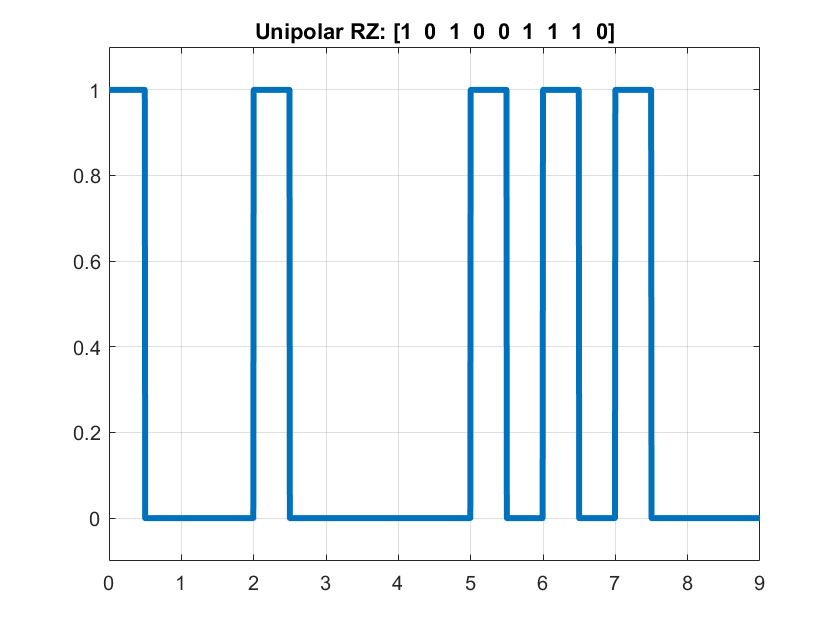

bits = [1 0 1 0 0 1 1 1 0];
bitrate = 1;

T = length(bits)/bitrate; % full time of bit sequence
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); % output signal

for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = 0;
  else
    x(i*n+1:(i+1)*n) = 0;
  end
end

figure;
plot(t,x,'LineWidth', 3);
axis([0 t(end) -0.1 1.1])
grid on;
title(['Unipolar RZ: [' num2str(bits) ']'])

## Polar RZ

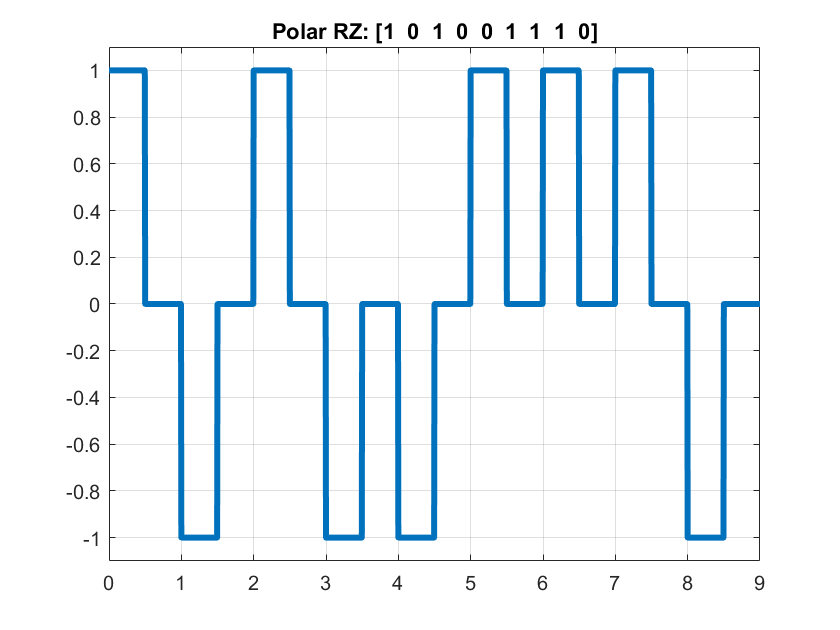

bits = [1 0 1 0 0 1 1 1 0];
bitrate = 1;

T = length(bits)/bitrate; % full time of bit sequence
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); % output signal

for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = 0;
  else
    x(i*n+1:(i+0.5)*n) = -1;
    x((i+0.5)*n+1:(i+1)*n) = 0;
  end
end

figure;
plot(t,x,'LineWidth', 3);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Polar RZ: [' num2str(bits) ']'])

## Bipolar RZ

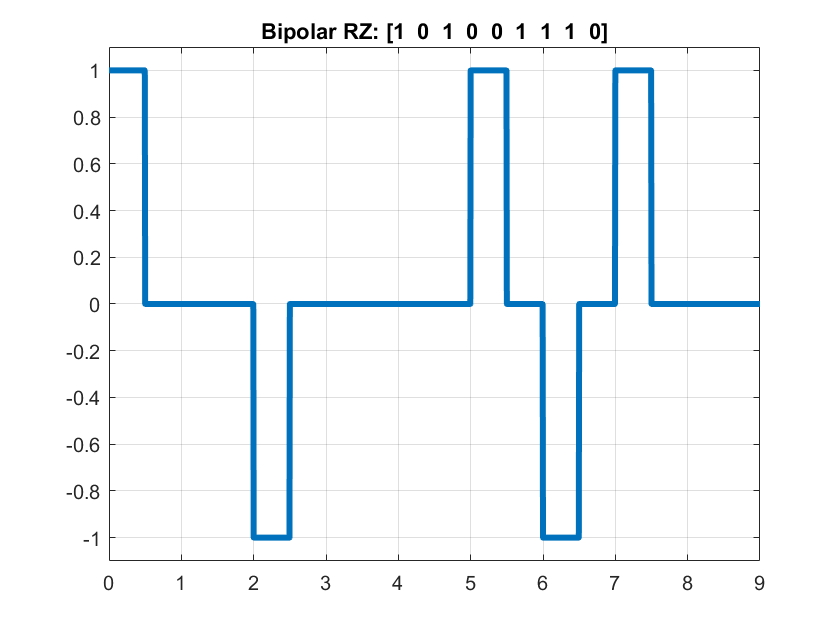

bits = [1 0 1 0 0 1 1 1 0];
bitrate = 1;

T = length(bits) / bitrate; % full time of bit sequence
n = 200;
N = n * length(bits);
dt = T / N;
t = 0:dt:T;
x = zeros(1, length(t)); % output signal

next_bit_is_one = true;

for i = 0:length(bits)-1
  if bits(i+1) == 1
    if next_bit_is_one
      x(i*n+1:(i+0.5)*n) = 1;
      x((i+0.5)*n+1:(i+1)*n) = 0;
    else
      x(i*n+1:(i+0.5)*n) = -1;
      x((i+0.5)*n+1:(i+1)*n) = 0;
    end
    next_bit_is_one = ~next_bit_is_one;
  else
    x(i*n+1:(i+1)*n) = 0;
  end
end


figure;
plot(t, x, 'LineWidth', 3);
axis([0 t(end) -1.1 1.1]);
grid on;
title(['Bipolar RZ: [' num2str(bits) ']']);

## Polar Manchester

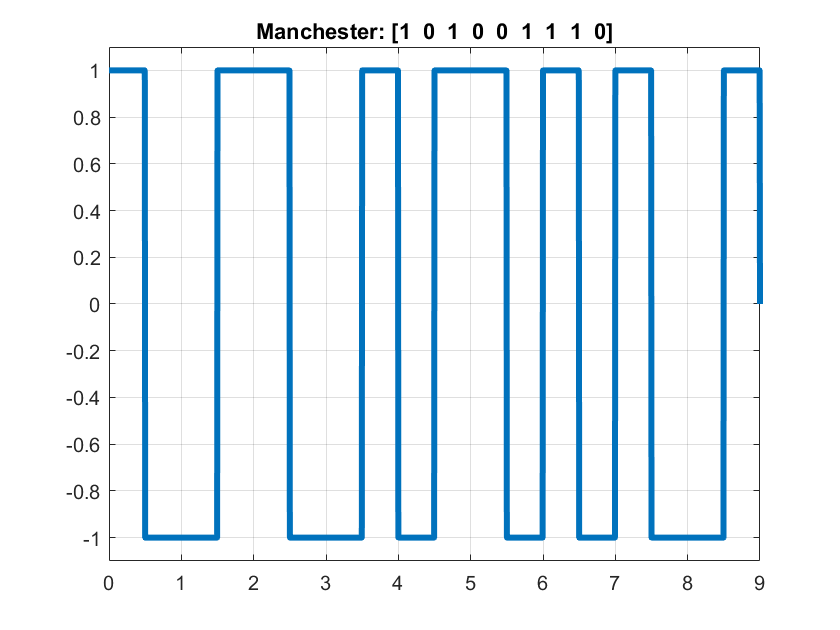

bits = [1 0 1 0 0 1 1 1 0];
bitrate = 1;

T = length(bits)/bitrate; % full time of bit sequence
n = 200;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t)); % output signal

voltage_level = 1; % Initialize previous level

for i = 0:length(bits)-1
  if bits(i+1) == 1
    x(i*n+1:(i+0.5)*n) = 1;
    x((i+0.5)*n+1:(i+1)*n) = -1;
  else
    x(i*n+1:(i+0.5)*n) = -1;
    x((i+0.5)*n+1:(i+1)*n) = 1;
  end
end

figure;
plot(t,x,'LineWidth', 3);
axis([0 t(end) -1.1 1.1])
grid on;
title(['Manchester: [' num2str(bits) ']'])